# **	Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Nombre:  Isaac Marval, Diego Pena**

**Fecha: 21-11-2025**

# Tema 4. Ejercicio 2. Transformada de Fourier

El objetivo de la práctica es calcular la transformada de Fourier de todos los objetos de una imagen y utilizar sólo las componentes más significativas de cada objeto para reconstruirlos.

Step 1) Read Image

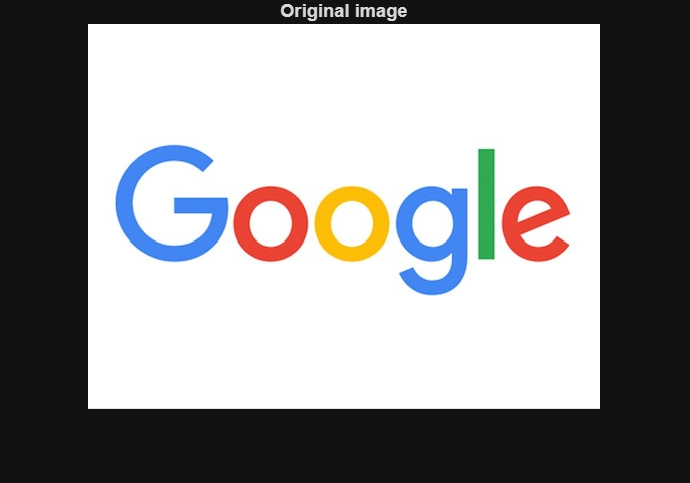

        close all
        clear all
    
        imgOriginal = imread('google.jpg');
        figure;
        imshow(imgOriginal);
        title('Original image');

Step 2) Threshold the Image

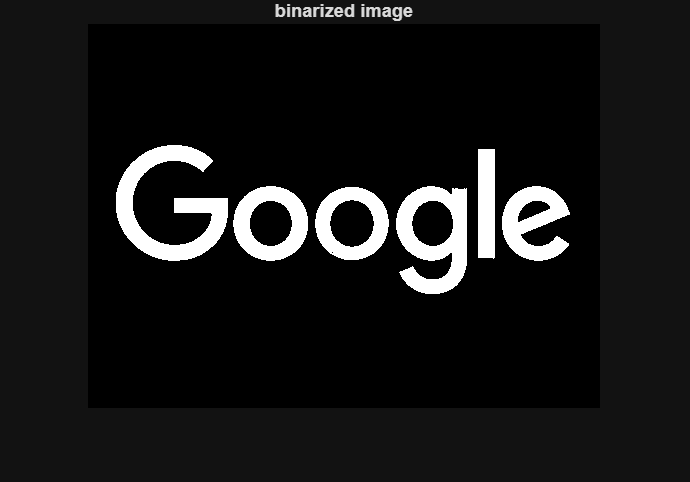

        if size(imgOriginal,3) == 3
            imgOriginal = rgb2gray(imgOriginal); 
        end
        imgBW = imbinarize(imgOriginal);
        imgBW = imcomplement(imgBW);
        
        figure;
        imshow(imgBW);
        title('binarized image');

Step 4) Find the external Boundaries

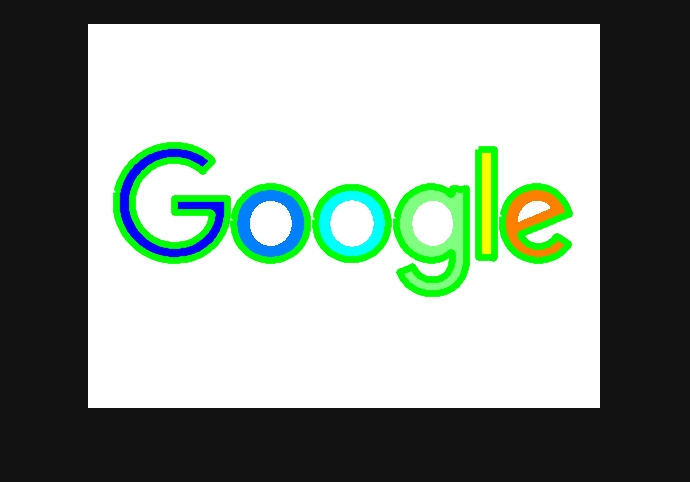

        [B,L] = bwboundaries(imgBW,'noholes');
        figure
        imshow(label2rgb(L, @jet, [1.0 1.0 1.0]))
        hold on
        for k = 1:length(B)
           boundary = B{k};
           plot(boundary(:,2), boundary(:,1), 'g', 'LineWidth', 4);
        end  

Step 5)  Fourier transform 

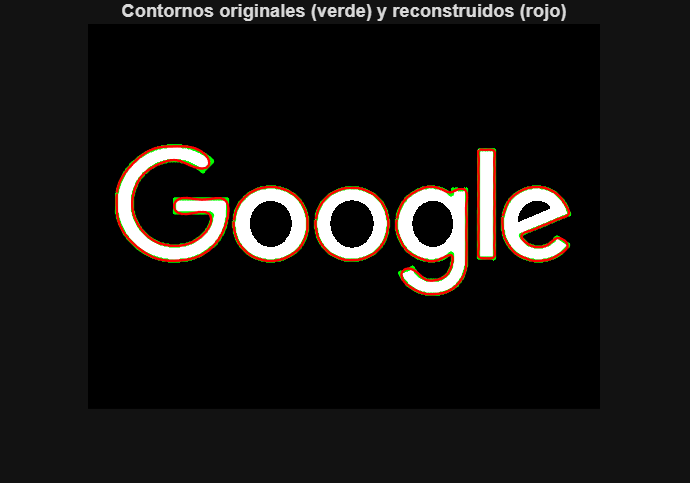

figure; imshow(imgBW); hold on;
title('Contornos originales (verde) y reconstruidos (rojo)');

num_componentes = 30;   % Prueba con 5, 10, 20, 50... para ver la diferencia

for k = 1:length(B)
    boundary = B{k};          % Nx2: [fila, columna]
    
    % 1) Transformada de Fourier del contorno
    F = fourier_transform(boundary);   % -> lista de números complejos
    
    % 2) Reconstrucción del contorno usando solo "num_componentes"
    boundary_rec = fourier_inv_transform(F, num_componentes);
    % Suponemos que boundary_rec también devuelve Nx2: [fila, columna]
    
    % 3) Representar contorno original y reconstruido
    % Original en verde
    plot(boundary(:,2), boundary(:,1), 'g', 'LineWidth', 2);
    
    % Reconstruido en rojo
    plot(boundary_rec(:,2), boundary_rec(:,1), 'r', 'LineWidth', 1.5);
end

hold off;

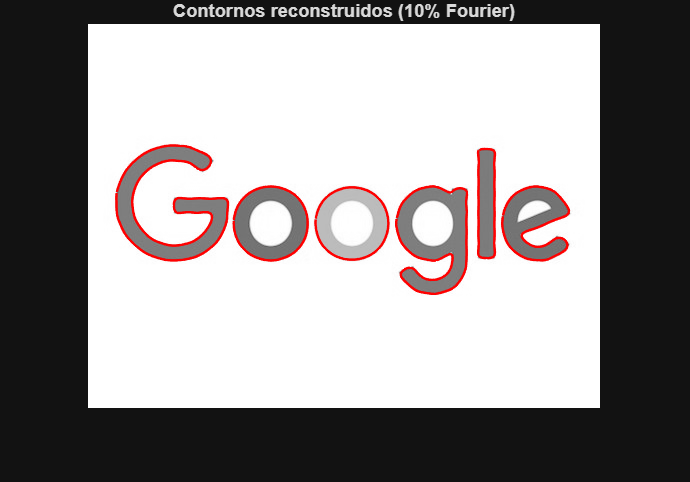


figure; 
imshow(imgOriginal); 
title('Contornos reconstruidos (10% Fourier)');
hold on;

for k = 1:length(B)
    boundary = B{k};      % Nx2: [fila, columna]

    % 1) Transformada de Fourier del contorno
    F = fourier_transform(boundary);   % vector de números complejos

    % 2) Calcular nº de componentes = 10% del total
    total_comp = length(F);
    num_comp = ceil(0.10 * total_comp);   % 10%

    % 3) Reconstrucción del contorno usando solo el 10% de componentes
    boundary_rec = fourier_inv_transform(F, num_comp);
    % Suponemos que devuelve Nx2: [fila, columna]

    % 4) Dibujar el contorno reconstruido sobre la imagen original
    plot(boundary_rec(:,2), boundary_rec(:,1), 'r', 'LineWidth', 1.5);
end

hold off;

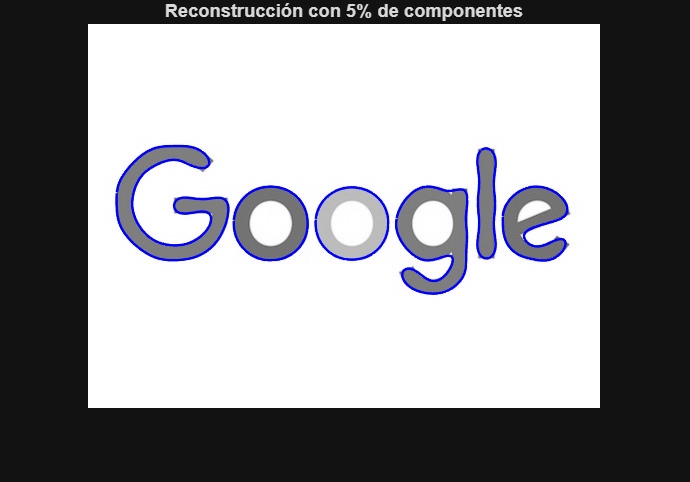

figure; 
imshow(imgOriginal); 
title('Reconstrucción con 5% de componentes');
hold on;

for k = 1:length(B)
    boundary = B{k};

    % Transformada
    F = fourier_transform(boundary);

    % 5% de componentes
    n = ceil(0.05 * length(F));

    % Reconstrucción
    boundary_rec = fourier_inv_transform(F, n);

    % Dibujar
    plot(boundary_rec(:,2), boundary_rec(:,1), 'b', 'LineWidth', 1.5);
end

hold off;

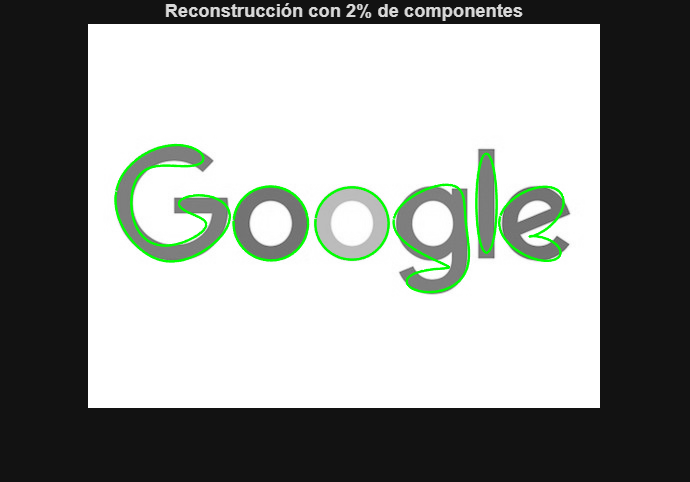


figure; 
imshow(imgOriginal); 
title('Reconstrucción con 2% de componentes');
hold on;

for k = 1:length(B)
    boundary = B{k};

    % Transformada
    F = fourier_transform(boundary);

    % 2% de componentes
    n = ceil(0.02 * length(F));

    % Reconstrucción
    boundary_rec = fourier_inv_transform(F, n);

    % Dibujar
    plot(boundary_rec(:,2), boundary_rec(:,1), 'g', 'LineWidth', 1.5);
end

hold off;

%Comparativa:
%    10%	Forma bastante fiel, contorno suavizado pero reconocible
%    5%	    Pérdida notable de detalle, contorno redondeado
%    2%	    Las letras casi irreconocibles y con formas muy simplificadas

%    Este comportamiento es normal: al reducir los coeficientes de Fourier, eliminas componentes de alta frecuencia y pierdes detalles.


Se pide: 

- Complete el paso 5, utilizando la función `fourier_transform(),` proporcionada con este enunciado, para obtener la transformada de Fourier de cada uno de los objetos etiquetados.

- Obtenga los contornos reconstruidos de los objetos etiquetados realizando la transformada inversa de Fourier con la función **fourier_inv_transform()**, también incluida con el enunciado. Visualice los comentarios de la función para realizar la reconstrucción utilizando solamente el 10**%** del total de las componentes. Dibuje el contorno recuperado sobre la figura original utilizando hold on y compruebe si el contorno se ajusta a las letras de la imagen. 

- Repita el proceso reduciendo el número de componentes utilizados para la reconstrucción al 5**%** del total**.**

- Repita el proceso reduciendo el número de componentes utilizados para la reconstrucción al 2**%** del total

- Compare los resultados de los puntos 2. 3. y 4. y explique sus conclusiones. 